close
clear
clc
s = tf('s');

## A

A = [0      0       1 0;   
         0      0       0 1;
         0 483.13 -28.262 0;
         0 -837.21 28.262 0];
display(A)

A =          0         0    1.0000         0
         0         0         0    1.0000
         0  483.1300  -28.2620         0
         0 -837.2100   28.2620         0


## Poles

sys_p = eig(A);
display(sys_p)

sys_p =    0.0000 + 0.0000i
  -6.3106 +24.4945i
  -6.3106 -24.4945i
 -15.6407 + 0.0000i


## B

B = [0;
     0;
     49.708;
     -49.708];
display(B)

B =          0
         0
   49.7080
  -49.7080


## C

C = [eye(2) zeros(2)];
display(C)

C =      1     0     0     0
     0     1     0     0


## D and U

D = [0;
     0];
display(D)

D =      0
     0


U = 1;
display(U)

U = 1

## Transfer Function

[Num , Den] = ss2tf(A, B, C, D);
display(Num), display(Den)

Num = 	1.0e+04 *

         0         0    0.0050    0.0000    1.7601
         0         0   -0.0050    0.0000   -0.0000


Den = 	1.0e+04 *

    0.0001    0.0028    0.0837    1.0007         0


G_theta = tf(Num(1,:), Den);
G_theta_pole = pole(G_theta);
G_alfa = tf(Num(2,:), Den);
G_alfa_pole = pole(G_alfa);
display(G_theta), display(G_theta_pole)

G_theta =
 
     49.71 s^2 + 1.004e-26 s + 1.76e04
  ----------------------------------------
  s^4 + 28.26 s^3 + 837.2 s^2 + 1.001e04 s
 
Continuous-time transfer function.



G_theta_pole =    0.0000 + 0.0000i
  -6.3106 +24.4945i
  -6.3106 -24.4945i
 -15.6407 + 0.0000i


display(G_alfa), display(G_alfa_pole)

G_alfa =
 
    -49.71 s^2 + 3.532e-13 s - 5.198e-28
  ----------------------------------------
  s^4 + 28.26 s^3 + 837.2 s^2 + 1.001e04 s
 
Continuous-time transfer function.



G_alfa_pole =    0.0000 + 0.0000i
  -6.3106 +24.4945i
  -6.3106 -24.4945i
 -15.6407 + 0.0000i


## Controlability Check

C_c = ctrb(A, B);
C_c_rank = rank(C_c);
if C_c_rank == length(A)
    disp("It is controlable!"), disp(C_c_rank)
else
    disp("It is not controlable!"), display(C_c_rank), display(length(A))
end

It is controlable!
     4



## Lead Controller

K_ctrl = 1;
p = 1;
z = 1;
alfa = p / z;
G_ctrl = alfa * (s + z) / (s + p);

## K as Gain

K_v = Num(9) / Den(4);
K_ctrl = 10 / K_v;
display(K_v), display(K_ctrl)

K_v = 1.7588

K_ctrl = 5.6856

[Gm, Pm] = margin(K_ctrl*G_theta);
alfa = (sind(22)+1)/(1-sind(22))

alfa = 2.1980

w_m = 5.9

w_m = 5.9000

p = sqrt(alfa * w_m^2)

p = 8.7471

z = p / alfa

z = 3.9796

T_ol = K_ctrl * alfa * ((s+z)/(s+p)) * G_theta;
T_cl = feedback(T_ol, 1);
margin(T_cl)
margin(T_ol)

## Lead Q

stepinfo(feedback(G_theta, 1))

ans = struct with fields:
        RiseTime: 1.0725
    SettlingTime: 1.9411
     SettlingMin: 0.9005
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 4.3560


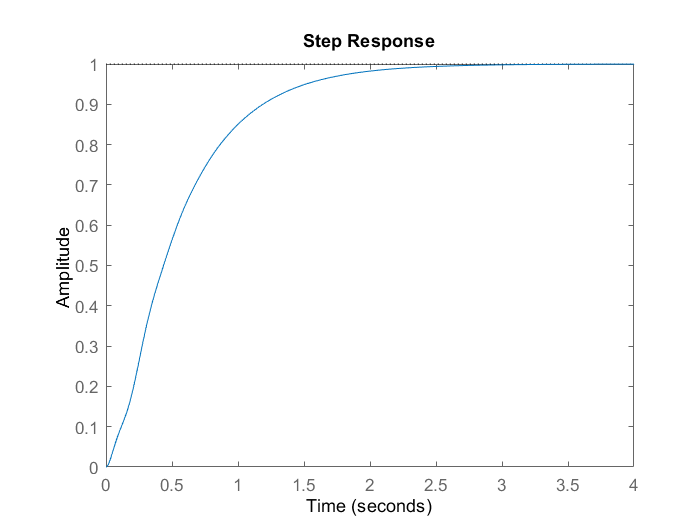

step(feedback(G_theta, 1))

stepinfo(feedback(G_alfa, 1))

ans = struct with fields:
        RiseTime: 1.9504e-10
    SettlingTime: 0.6784
     SettlingMin: -0.0565
     SettlingMax: 0.0187
       Overshoot: 1.7945e+11
      Undershoot: 5.9514e+10
            Peak: 0.0565
        PeakTime: 0.0931


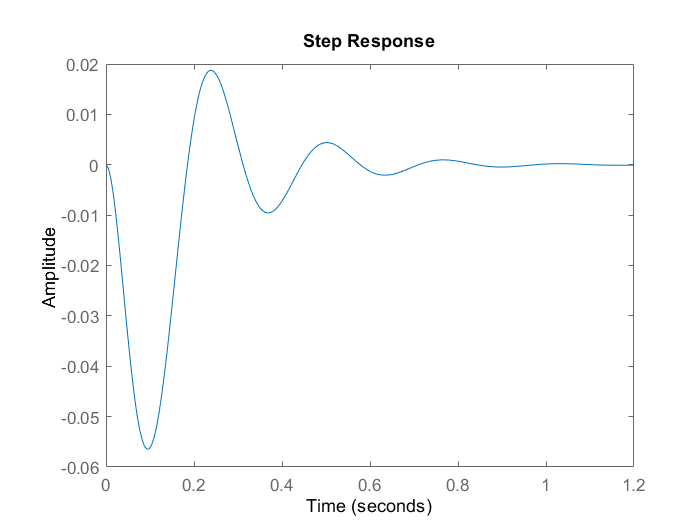

step(feedback(G_alfa, 1))

## Lag Controller

PM_lag = 75;
w_c_lag = 3.25;
beta_lag = 2.96;
z_lag = w_c_lag * 0.1;
p_lag = z_lag / beta_lag;
C_lag = (K_ctrl / beta_lag) * ((s+z_lag)/(s+p_lag));
T_ol_lag = series(C_lag, G_theta);
margin(T_ol)
T_cl_lag = feedback(T_ol_lag, 1);
margin(T_cl_lag)

## State Space Feed-Back

s_d_fb = [-5.04+1j*5.141 -5.04-1j*5.141 -100 -50];
K_ssfb = place(A, B, s_d_fb);

A_new = A - B*K_ssfb;
[N_ssfb, D_ssfb] = ss2tf(A_new, B, C, D);
G_t_ssfb = tf(N_ssfb(1,:),D_ssfb)

G_t_ssfb =
 
                 49.71 s^2 + 1.76e04
  --------------------------------------------------
  s^4 + 160.1 s^3 + 6564 s^2 + 5.817e04 s + 2.592e05
 
Continuous-time transfer function.



rlocus(G_t_ssfb)
stepinfo(G_t_ssfb)  

ans = struct with fields:
        RiseTime: 0.3744
    SettlingTime: 0.8688
     SettlingMin: 0.0611
     SettlingMax: 0.0706
       Overshoot: 3.9572
      Undershoot: 0
            Peak: 0.0706
        PeakTime: 0.6724
